# Part I: Camera Calibration using 3D calibration object

## Q1: Draw the image points

real world coordinate

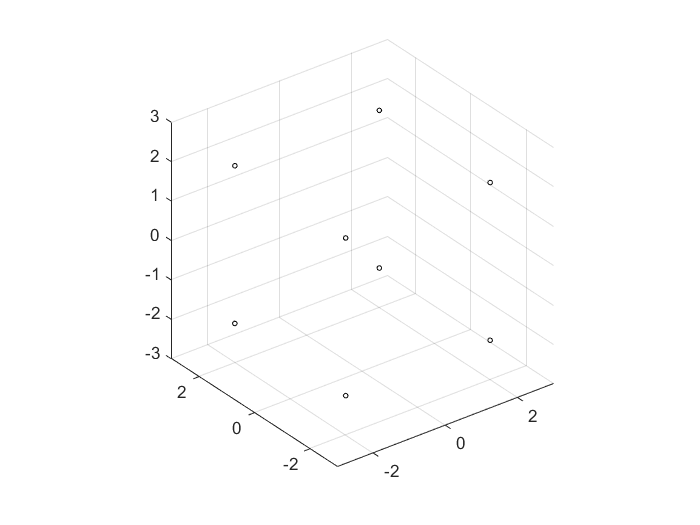

real_coordinate = [2 2 2;
                   -2 2 2;
                   -2 2 -2;
                   2 2 -2;
                   2 -2 2;
                   -2 -2 2;
                   -2 -2 -2;
                   2 -2 -2];
figure("Name", "Real world coordinate")
%f1 = axes
% circle and black
fig1 = scatter3(real_coordinate(:, 1), real_coordinate(:, 2), real_coordinate(:, 3), 8, "black", "o");
axis equal;
axis([-3, 3, -3, 3, -3, 3]);
grid on; 
saveas(fig1, './part1/1/1.jpg');

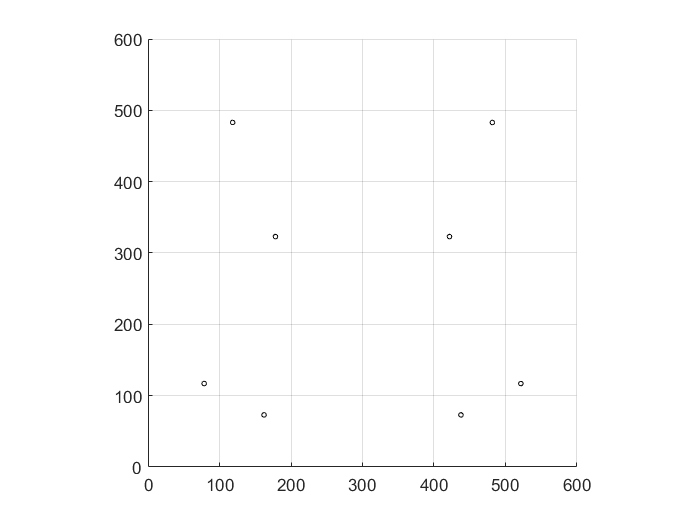


% pixel positions in the camera image
image_pixel = [422 323; 178 323; 118 483; 482 483;
               438 73; 162 73; 78 117; 522 117];
figure("Name", "Pixel positions in the camera image")
fig2 = scatter(image_pixel(:, 1), image_pixel(:, 2), 8, "black", "o");
axis equal;
axis([0, 600, 0, 600]);
grid on;
saveas(fig2, './part1/1/2.jpg');

clear figure;

## Q3: Print matrix P

[x, y] = size(real_coordinate);
P = zeros(2 * x, 3 * (y + 1));

for i = 1:x
    % return 2 rows.
    P(2 * i - 1: 2 * i, :) = cal_matrix_P(real_coordinate(i, :), image_pixel(i, :));
end
% print P
% disp("P=");
% disp(P)
P

P =      2     2     2     1     0     0     0     0  -844  -844  -844  -422
     0     0     0     0     2     2     2     1  -646  -646  -646  -323
    -2     2     2     1     0     0     0     0   356  -356  -356  -178
     0     0     0     0    -2     2     2     1   646  -646  -646  -323
    -2     2    -2     1     0     0     0     0   236  -236   236  -118
     0     0     0     0    -2     2    -2     1   966  -966   966  -483
     2     2    -2     1     0     0     0     0  -964  -964   964  -482
     0     0     0     0     2     2    -2     1  -966  -966   966  -483
     2    -2     2     1     0     0     0     0  -876   876  -876  -438
     0     0     0     0     2    -2     2     1  -146   146  -146   -73


% P;

## Q4: Print matrix M

[U,S,V] = svd(P);
% M by transposing the last column of row-order vector V
M = [V(1:4, end) V(5:8, end) V(9:12, end)]'; % vertcat in row order then transpose
% print M
% disp("M=");
% disp(M)
M

M =    -0.1925   -0.0283   -0.0786   -0.7346
   -0.0000   -0.2044   -0.0001   -0.6120
   -0.0000   -0.0001   -0.0003   -0.0024


## Q5: Print the Euclidean coordinates of the camera center

[m_U, m_Sigma, m_V_T] = svd(M);
% t is the unit singular vector of M (last col of V of SVD of M)
% center = (x, y, z)_T = (t1, t2, t3) / t4 by set t(4) = 1
t = m_V_T(:, end);
center = t(1: end - 1) / t(end)

center =    -0.0000
   -2.9912
   -8.2695


## Q6: Print matrix M'

M_prime = M(:, 1:3) /  M(3, 3)

M_prime =   734.6289  107.8955  299.9999
    0.0009  780.1442    0.2641
    0.0000    0.3597    1.0000


## Q7: Print R_x, theta_x, N

cos_theta_x = M_prime(3, 3) / sqrt(M_prime(3, 3)^2 + M_prime(3, 2)^2);
sin_theta_x = -M_prime(3, 2) / sqrt(M_prime(3, 3)^2 + M_prime(3, 2)^2);

% Print R_x
R_x = [1 0 0;
       0 cos_theta_x -sin_theta_x;
       0 sin_theta_x cos_theta_x;]

R_x =     1.0000         0         0
         0    0.9410    0.3384
         0   -0.3384    0.9410



% Use arcsin and get the radian of theta_x and change to degree
% Print theta_x
theta_x = asin(sin_theta_x) * 180 / pi

theta_x = -19.7812


% Print N
N = M_prime * R_x

N =   734.6289   -0.0000  318.8125
    0.0009  734.0199  264.2723
    0.0000         0    1.0627


## Q8: Calculate R_z and theta_z

n31 is small so no need for R_y rotation

R_y = diag([1, 1, 1]);

% Calculate R_z
cos_theta_z = N(2, 2) / sqrt(N(2, 1)^2 + N(2, 2)^2);
sin_theta_z = -N(2, 1)/sqrt(N(2, 1)^2 + N(2, 2)^2);
R_z = [cos_theta_z -sin_theta_z 0;
       sin_theta_z cos_theta_z 0;
       0 0 1;]

R_z =     1.0000    0.0000         0
   -0.0000    1.0000         0
         0         0    1.0000


theta_z = asin(sin_theta_z) * 180 / pi

theta_z = -7.2204e-05

## Q9: Calculate K by M'/(R_x*R_y)

R_z is factorized out

K = M_prime / (R_x * R_y);

% Print K
K = K / K(3,3)

K =   896.6817  247.8504  299.9999
    0.0011  896.1566 -321.9619
    0.0000    0.8262    1.0000



%{
    K = [F_x s C_x;
         0 F_y C_y;
         0 C_y 1;]
    Focal length in pixels = F
    Optical center in pixels = C
%}
% Print focal lengths
fcoal_lengths = [K(1, 1), K(2, 2)]

fcoal_lengths =   896.6817  896.1566



% Pixel coordinates of the image center of the camera
img_center = [K(1, 3), K(2, 3)]

img_center =   299.9999 -321.9619
